## Оценка параметров реального китайского привода по данным из csv файла 

### Читаем CSV файл

clear; clc;
% csv = readmatrix("csv/rchi_step_test.csv");
% csv = readmatrix("csv/rchi_sin1.csv");
% csv = readmatrix("csv/chi_reverse_sin_dt10.csv");
% csv = readmatrix("csv/sin_chi.csv");
% csv = readmatrix("csv/chi_sin_dt10_v1.csv");
% csv = readmatrix("csv/rchi_6v_test.csv");
% csv = readmatrix("csv/chi_step_test.csv");
csv = readmatrix("csv/rchi_sin_voltage.csv");

crop = 10;
data_length = length(csv(:,2))-1 - crop

data_length = 490

% data_length = 2500
time = csv(2:data_length+1, 2);    % мкс
% q_orig = csv(2:data_length+1, 3) * pi/180;  % рад
% w_orig = csv(2:data_length+1, 4) * pi/180;  % рад/c
% dw_orig = csv(2:data_length+1, 5) * pi/180;  % рад/c^2
% input = csv(2:data_length+1, 6) / 100 * 6.0;    % В
% current = csv(2:data_length+1, 7) - 0.048;  % А
input = csv(2:data_length+1, 7);    % В
current = csv(2:data_length+1, 8);  % А
% current = csv(2:data_length+1, 7);  % А

q_orig = csv(2:data_length+1, 3);  % рад
w_orig = csv(2:data_length+1, 4);  % рад/c
dw_orig = csv(2:data_length+1, 5);  % рад/c^2
dI_orig = csv(2:data_length+1, 5);
dI_orig(1) = 0;

t_start = time(1);
time = (time - t_start)/1000000;    % с
tf = time(data_length)

tf = 6.8460


% w_orig = smooth(w_orig, 6);
% dw_orig = smooth(dw_orig, 50);
% current = smooth(current, 15);

% w_orig = smooth(w_orig, 5);
dw_orig = smooth(dw_orig, 5);
% current = smooth(current, 5);

dt_sum = 0;
for k = 2:data_length
    dt = time(k) - time(k-1);
    dt_sum = dt_sum + dt;
    dI_orig(k) = (current(k)-current(k-1))/dt;
end

V = input;

dI_orig = smooth(dI_orig, 15);
input_sm = smooth(input,15);
w_sm = smooth(w_orig,15);
dI_orig = smooth(dI_orig, 10);

dt = dt_sum/(data_length-1)

dt = 0.0140

Imax = 0.07;
Istall = 1.24;
Wmax = 21;
Mmax = 0.2281;

Km = Mmax/Istall

Km = 0.1840

Lam = Km*Imax/Wmax

Lam = 6.1317e-04

R = 6/Istall

R = 4.8387

Kw = (6-R*Imax)/Wmax

Kw = 0.2696

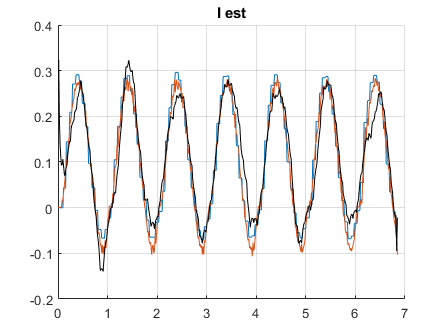


J = 0.5*0.024*(0.068/2)^2;
L = 2.9;

L = 0.0011;
R = 3.2298;
Kw = 0.2326;
Km = 0.1078;
J = 2.3865e-04;
Lam = 0.0010;

M_ext_orig = J*dw_orig + Lam*w_sm - Km*current;
I_est_orig = J*dw_orig/Km + Lam*w_sm/Km;
I_est_orig_u = (input_sm - Kw*w_sm)/R;
% I_est = (input)/R;
% I_est = Lam*w_orig/Km;
I_est = input/R - Kw/R*w_orig - J/Km*dw_orig;

figure;
hold on
plot(time, current)
plot(time, I_est_orig)
plot(time, I_est_orig_u, "black")
% plot(time, I_est, "red")
hold off
title("I est")
xlim("auto")
ylim("auto")
grid on

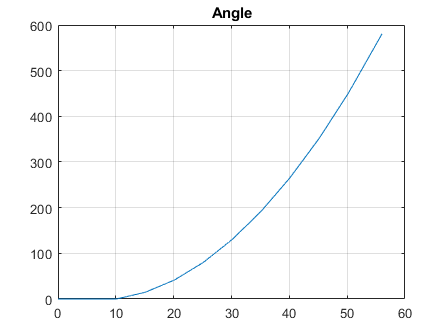

figure;
plot(time, q_orig)
title("Angle")
xlim("auto")
ylim("auto")
grid on

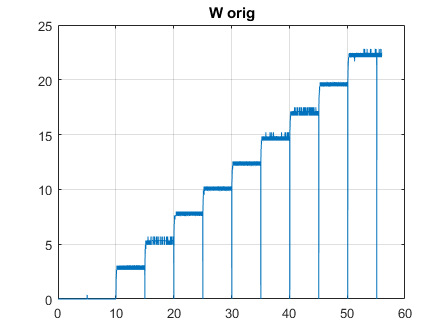


figure;
plot(time, w_orig)
title("W orig")
xlim("auto")
ylim("auto")
grid on

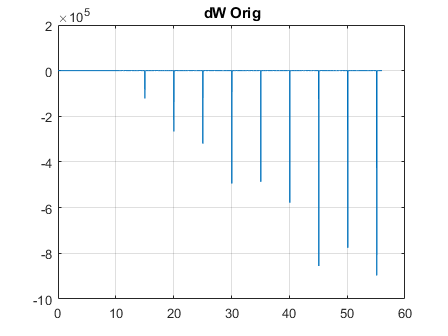


figure;
plot(time, dw_orig)
title("dW Orig")
xlim("auto")
ylim("auto")
grid on

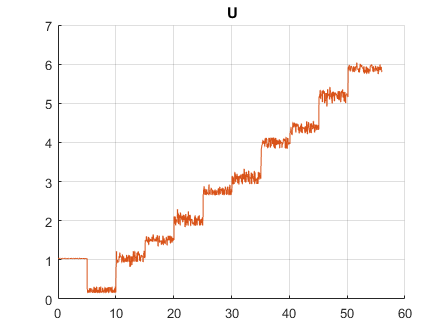


figure;
hold on
plot(time, input)
plot(time, V)
hold off
title("U")
xlim("auto")
ylim("auto")
grid on

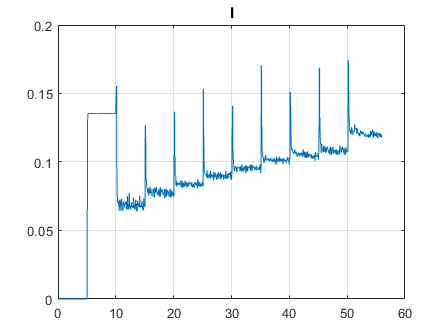


figure;
plot(time, current)
title("I")
xlim("auto")
ylim("auto")
grid on

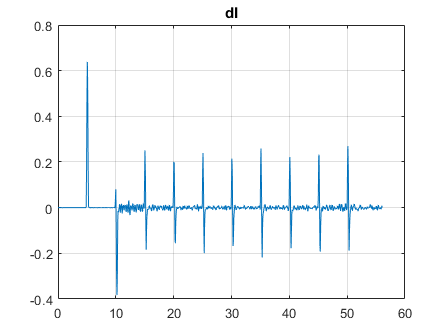


figure;
plot(time, dI_orig)
title("dI")
xlim("auto")
ylim("auto")
grid on

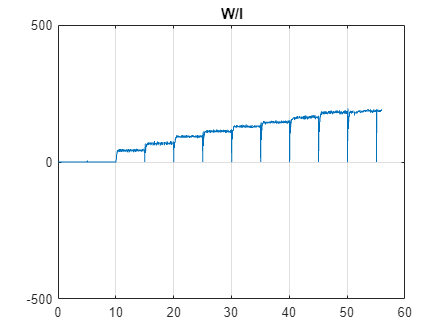


% figure;
% plot(time, M_ext_orig)
% title("M ext")
% xlim("auto")
% ylim("auto")
% grid on

figure;
% plot(time, input./current)
plot(time, w_orig./current)
% title("U/I")
title("W/I")
xlim("auto")
% ylim("auto")
ylim([-500 500])
grid on

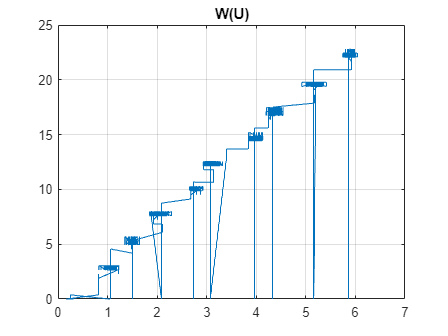


figure;
plot(input, w_orig)
% title("W/U")
title("W(U)")
xlim("auto")
ylim("auto")
% ylim([10 15])
grid on

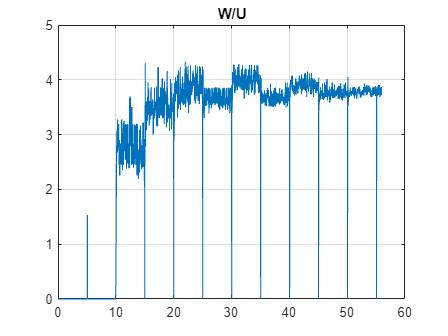


figure;
plot(time, w_orig./input)
title("W/U")
xlim("auto")
ylim("auto")
% ylim([10 15])
grid on

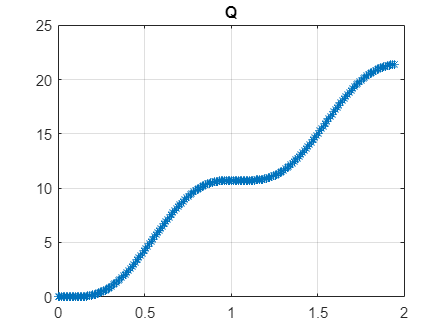

% start = 3500;
% finish = 3550;

start = 1;
finish = 200;

figure;
plot(time(start:finish), q_orig(start:finish), '*-')
% plot(time(start:finish), ticks(start:finish))
title("Q")
xlim("auto")
ylim("auto")
grid on

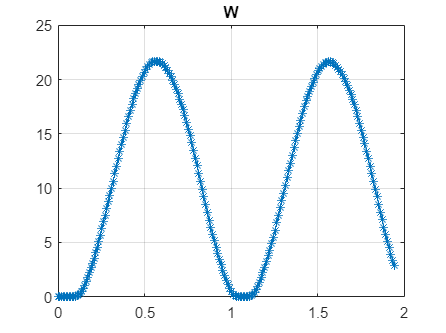


figure;
plot(time(start:finish), w_orig(start:finish), '*-')
title("W")
xlim("auto")
ylim("auto")
grid on

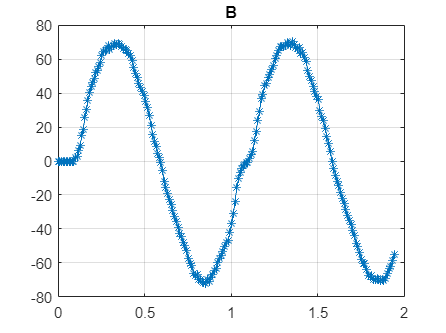


figure;
plot(time(start:finish), dw_orig(start:finish), '*-')
title("B")
xlim("auto")
ylim("auto")
grid on

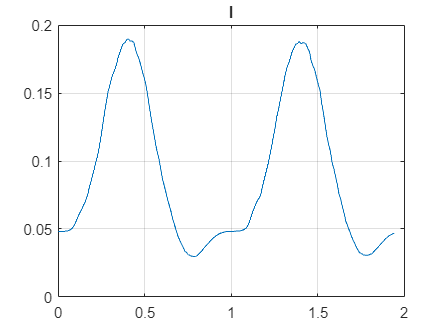


figure;
% plot(time(start:finish), current(start:finish), '*-')
plot(time(start:finish), current(start:finish))
title("I")
xlim("auto")
ylim("auto")
grid on

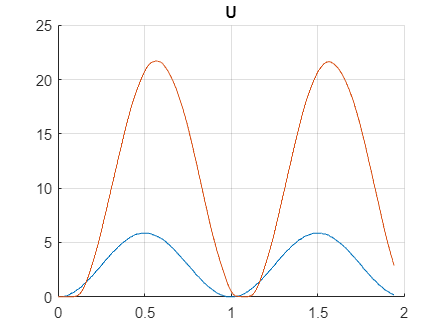


figure;
hold on
% plot(time(start:finish), input(start:finish), '*-')
plot(time(start:finish), input(start:finish))
plot(time(start:finish), w_orig(start:finish))
hold off
title("U")
xlim("auto")
ylim("auto")
grid on

### Parameters identification with kalman filter model with load

L = 0.0314;
J = 0.0011;
R = 11.8227;
Kw = 0.2923;
Km = Kw;
Lam = 0.0019; 
 
% R = 8.5243
% Kw = 0.2359
% Km = 1.1730e-10
% Lam = 3.5124e-13

% V3 + load
% x = [w dw I]'
% u = [Mext u]'
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L];
B = [1/J 0;
     0   Km/(J*L);
     0   1/L];
C = eye(3);
D = [0 0 0]';

C_lqe = [1 0 0;
         0 1 0;
         0 0 1];
[Te, De] = eig(A);
% Cc = ctrb(A,B)
% Cob = obsv(A, C_lqe)
% rank(Cc)
% rank(Cob)

Vd_w = 1e2;
Vd_dw = 1e3;
Vd_I = 1;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];

Vn = [1e1 0 0;
      0 1e7 0;
      0 0 1];

% dt = 0.01
dt
[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, dt);
Kf
% "<< " + Kf(1,1) + ", " + Kf(1,2) + ", " + Kf(1,3) + ", " ...
%       + Kf(2,1) + ", " + Kf(2,2) + ", " + Kf(3,3) + ", " ...
%       + Kf(3,1) + ", " + Kf(3,2) + ", " + Kf(3,3)

betta = 0.3; % коэффициент регуляризации
k0 = 2; % начальное значение матрицы коэффициентов
% betta = 7 % коэффициент регуляризации
% k0 = 600 % начальное значение матрицы коэффициентов
I = eye(4); % диагональная единичная матрица
GAMMA_0 = k0.*I; % матрица начальных значений коэффициентов
% GAMMA_0(3,3) = 50;

Th_hat = [0; 0; 0; 0];
Th_hat(1) = R;
Th_hat(2) = Kw;
Th_hat(3) = Km;
Th_hat(4) = Lam;
Th_hat;
Th_hat_start = Th_hat
dTh_hat = [0; 0; 0; 0];

G_hat = GAMMA_0;
dG_hat = zeros(4, 4);

% dTh_hat = G_hat * fi * (u - fi' * Th_hat)
% dG_hat = -G_hat * fi * fi' * G_hat + betta * G_hat

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);
dI_arr = zeros(1, data_length);
Mext = 0;
Mext_arr = zeros(1, data_length);

At = expm(A*dt);
Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B;
Bt = real(Bt);
A_hat = (At-Kf*C_lqe);
B_hat = [Bt Kf];

k_di = 0.9;
Mext_sum = 0;
% Mext = 7e-3;

% for k = 2:20
for k = 2:data_length
    dt = time(k) - time(k-1);
    u_act = input(k-1);

%     u = [Mext input(k-1) (C_lqe*[w_orig(k-1) dw_orig(k-1) current(k-1)]')']';
    u = [0 input(k-1) (C_lqe*[w_orig(k-1) dw_orig(k-1) current(k-1)]')']';
    x_arr(:, k) = A_hat*x_arr(:, k-1)+B_hat*u;
    x_arr(:, k) = real(x_arr(:, k));
    
    w_act = x_arr(1, k-1);
    dw_act = x_arr(2, k-1);
    I_act = x_arr(3, k-1);
    dI_act = (x_arr(3, k)-x_arr(3, k-1))/dt;

%     w_act = w_orig(k-1);
%     dw_act = dw_orig(k-1);
%     I_act = current(k-1);
%     dI_act = (current(k)-current(k-1))/dt;
%     dI_act = dI_orig(k-1);

    dI_arr(k) = dI_arr(k-1)*(1-k_di) + k_di*dI_act;
    dI_act = dI_arr(k);
    q_arr(k) = q_arr(k-1) + w_act*dt;

    Mext = J*x_arr(2,k) + Th_hat(3)*x_arr(1,k) - Th_hat(2)*x_arr(3,k);
    Mext_arr(k) = real(Mext);
    Mext_sum = Mext_sum + Mext;

    phi = [I_act  0;
           w_act  0;
           0  -I_act;
           0  w_act];
     phi_T = phi';

    %Gamma G_hat
    dG_hat = -G_hat * phi * phi_T * G_hat + betta * G_hat;
    G_hat = G_hat + dG_hat * dt;

    U = [u_act; 0];
%     U = [u_act; Mext];

    Aa = -phi_T * Th_hat + U;
    dTh_hat =  G_hat * phi * Aa;
   
    Th_hat = Th_hat + dTh_hat * dt;   
end

Th_hat_start
Th_hat
eR = Th_hat(1)
eKw = Th_hat(2)
eKm = Th_hat(3)
eLam = Th_hat(4)
eJ = J;
eL = L;

start = 1;
% finish = 500;
finish = data_length;

figure
plot(time(start:finish), (q_orig(start:finish)'-real(q_arr(start:finish))))
% plot(time, q_arr)
grid on
title("q error")
xlim("auto")
ylim("auto")

% figure
% plot(time, dticks'-real(x_arr(1, :)))
% % plot(time, q_arr)
% grid on
% title("dq error")
% xlim("auto")
% ylim("auto")

figure
hold on
plot(time(start:finish), q_orig(start:finish))
plot(time(start:finish), q_arr(start:finish), "--")
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

figure
hold on
plot(time(start:finish), w_orig(start:finish))
plot(time(start:finish), x_arr(1, start:finish), "LineWidth", 1, "LineStyle", "--")
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

figure
hold on
plot(time(start:finish), dw_orig(start:finish))
plot(time(start:finish), x_arr(2, (start:finish)), "LineWidth", 1)
hold off
grid on
title("dW")
xlim("auto")
ylim("auto")
% ylim([-60 60])
legend("Original", "Estimated filtered")

figure
hold on
plot(time(start:finish), current(start:finish))
plot(time(start:finish), x_arr(3, (start:finish)))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

figure
hold on
plot(time(start:finish), dI_arr(start:finish))
hold off
grid on
title("dI")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

figure
plot(time, Mext_arr)
grid on
title("Mext")
xlim("auto")
ylim("auto")

Ah = [-eLam/eJ eKm/eJ; -eKw/eL -eR/eL];
Bh = [-1/eJ 0; 0 1/eL];
C = [1 0; 0 1];
D = [0 0; 0 0];

A;
A = Ah;
B;
B = Bh;

Amp = 3;
Bias = 3;
W = 1;
fi = 3.1415;
% Mext = 6e-3;
Mext = 0;
U_nominal = 6.0;

Const_input = [Amp Bias W fi Mext];

out1 = sim('motor_model_sim.slx', tf);
o = out1.simout;

### Parameters identification with kalman filter model with load FULL

L = 0.0314;
J = 0.0011;
R = 11.8227;
Kw = 0.2923;
Km = Kw;
Lam = 0.0019; 

% from calculator
Imax = 0.07;
Istall = 1.24;
Wmax = 21;
Mmax = 0.2281;
% Mmax = 0.5;

Km = Mmax/Istall

Km = 0.1840

Lam = Km*Imax/Wmax

Lam = 6.1317e-04

R = 5.9/Istall

R = 4.7581

Kw = (5.9-R*Imax)/Wmax

Kw = 0.2651


% J = 0.5*0.024*(0.068/2)^2;
J = 0.024*(0.068/2)^2;
% Km = 0.18395;
% Kw = 0.2516;
% R = 4.8387;
% Lam = 52.906e-5;

Kw = 0.2451;
R = 2.1902;
Lam = 0.0017;
Km = 0.19;

L = 29e-5;


L = 0.0011;
R = 3.2298;
Kw = 0.2326;
% Km = 0.1078;
J = 2.3865e-04;
Lam = 0.0010;

L = 6.5895e-05;
R = 3.3201;
Kw = 0.2317;
Km = 0.1864;
J = 4.1286e-04;
Lam = 0.0018;


% L = 1.0113;
% J = 2.9473e-04;
% R = 12.3326;
% Kw = 0.2306;
% Km = Kw;
% Lam = 7.3227e-04;

L = 1.4262;
R = 1.1218*2;
Kw = 0.2775;
Km = 1.0042;
% J = 0.0036;
J = 0.5*0.024*(0.068/2)^2;
Lam = 0.0049;

eL = 1.8317;
eR = 11.8417;
eKw = 0.2365;
eKm = 6.5429e-05;
eJ = 5.9580e-08;
eLam = 2.0960e-07;

% L = eL;
% R = eR;
% Kw = eKw;
% Km = eKm;
% J = eJ;
% Lam = eLam;

% V3 + load
% x = [w dw I]'
% u = [Mext u]'
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L];
B = [1/J 0;
     0   Km/(J*L);
     0   1/L];
C = eye(3);
D = [0 0 0]';

C_lqe = [1 0 0;
         0 1 0;
         0 0 1];
[Te, De] = eig(A);
% Cc = ctrb(A,B)
% Cob = obsv(A, C_lqe)
% rank(Cc)
% rank(Cob)

Vd_w = 1;
Vd_dw = 1;
Vd_I = 1e2;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];

Vn = [1 0 0;
      0 1 0;
      0 0 1];

% dt = 0.01
dt

dt = 0.0099

[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, dt);
Kf

Kf =     1.0000   -0.0000    0.0019
   -0.0000    1.0000    0.0000
    0.0019    0.0000    0.8462



betta = 0.2; % коэффициент регуляризации
k0 = 1; % начальное значение матрицы коэффициентов
% betta = 7 % коэффициент регуляризации
% k0 = 600 % начальное значение матрицы коэффициентов
I = eye(6); % диагональная единичная матрица
GAMMA_0 = k0.*I; % матрица начальных значений коэффициентов
% GAMMA_0(1,1) = 1;
% GAMMA_0(2,2) = 1e-1;
% GAMMA_0(3,3) = 1;
GAMMA_0(4,4) = 1e-1;
% GAMMA_0(5,5) = 1;
% GAMMA_0(6,6) = 1e-1;

Th_hat = [0; 0; 0; 0; 0; 0];
Th_hat(1) = L;
Th_hat(2) = R;
Th_hat(3) = Kw;
Th_hat(4) = Km;
Th_hat(5) = J;
Th_hat(6) = Lam;
Th_hat;
Th_hat_start = Th_hat;
dTh_hat = [0; 0; 0; 0; 0; 0];

G_hat = GAMMA_0;
dG_hat = zeros(6,6);

% dTh_hat = G_hat * fi * (u - fi' * Th_hat)
% dG_hat = -G_hat * fi * fi' * G_hat + betta * G_hat

x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);
dI_arr = zeros(1, data_length);
Mext = 0;
Mext_arr = zeros(1, data_length);


At = expm(A*dt);
Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B;
Bt = real(Bt);
A_hat = (At-Kf*C_lqe);
B_hat = [Bt Kf];

k_di = 0.2;
Mext_sum = 0;
% Mext = 7e-3;

for k = 2:data_length
% for k = 2:80
    dt = time(k) - time(k-1);
    u_act = input(k-1);

%     u = [-Mext input(k-1) (C_lqe*[w_orig(k-1) dw_orig(k-1) current(k-1)]')']';
%     u = [0 input(k-1) (C_lqe*[w_orig(k-1) dw_orig(k-1) current(k-1)]')']';
%     x_arr(:, k) = A_hat*x_arr(:, k-1)+B_hat*u;
%     x_arr(:, k) = real(x_arr(:, k));
%     
%     w_act = x_arr(1, k-1);
%     dw_act = x_arr(2, k-1);
%     I_act = x_arr(3, k-1);
%     dI_act = (x_arr(3, k)-x_arr(3, k-1))/dt;

    w_act = w_orig(k-1);
    dw_act = dw_orig(k-1);
    I_act = current(k-1);
%     dI_act = (current(k)-current(k-1))/dt;
    dI_act = dI_orig(k-1);

    dI_arr(k) = dI_arr(k-1)*(1-k_di) + k_di*dI_act;
    dI_act = dI_arr(k);
    q_arr(k) = q_arr(k-1) + w_act*dt;

    Mext = J*x_arr(2,k) + Th_hat(3)*x_arr(1,k) - Th_hat(2)*x_arr(3,k);
    Mext_arr(k) = real(Mext);

%     if I_act < 0
%         continue
%     end

    phi = [dI_act 0;
           I_act  0;
           w_act  0;
           0 -I_act;
           0 dw_act;
           0 w_act];
     phi_T = phi';

    %Gamma G_hat
    dG_hat = -G_hat * phi * phi_T * G_hat + betta * G_hat;
    G_hat = G_hat + dG_hat * dt;
    
%     U = [u_act; -Mext];
    U = [u_act; 0];

    Aa = -phi_T * Th_hat + U;
    dTh_hat =  G_hat * phi * Aa;
   
    Th_hat = Th_hat + dTh_hat * dt;   
    Th_hat = abs(Th_hat);
end

Th_hat_start

Th_hat_start =     0.0011
    3.2298
    0.2326
    0.1900
    0.0002
    0.0010


Th_hat

Th_hat =     0.0001
    3.3201
    0.2317
    0.1864
    0.0004
    0.0018


eL = Th_hat(1);
eR = Th_hat(2);
eKw = Th_hat(3);
eKm = Th_hat(4);
eJ = Th_hat(5);
eLam = Th_hat(6);

eL

eL = 6.5895e-05

eR

eR = 3.3201

eKw

eKw = 0.2317

eKm

eKm = 0.1864

eJ

eJ = 4.1286e-04

eLam

eLam = 0.0018

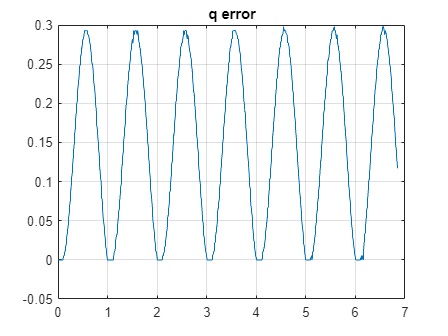

start = 1;
% finish = 500;
finish = data_length;

figure
plot(time(start:finish), (q_orig(start:finish)'-real(q_arr(start:finish))))
% plot(time, q_arr)
grid on
title("q error")
xlim("auto")
ylim("auto")

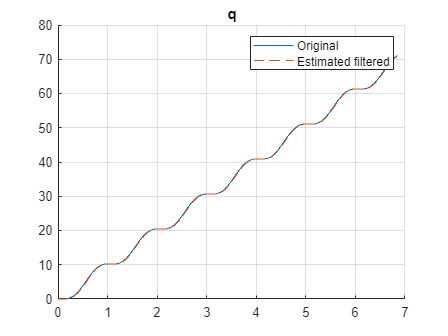


% figure
% plot(time, dticks'-real(x_arr(1, :)))
% % plot(time, q_arr)
% grid on
% title("dq error")
% xlim("auto")
% ylim("auto")

figure
hold on
plot(time(start:finish), q_orig(start:finish))
plot(time(start:finish), q_arr(start:finish), "--")
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

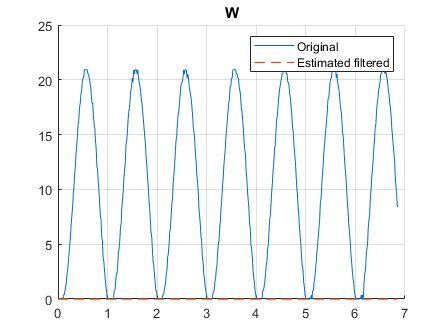


figure
hold on
plot(time(start:finish), w_orig(start:finish))
plot(time(start:finish), x_arr(1, start:finish), "LineWidth", 1, "LineStyle", "--")
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

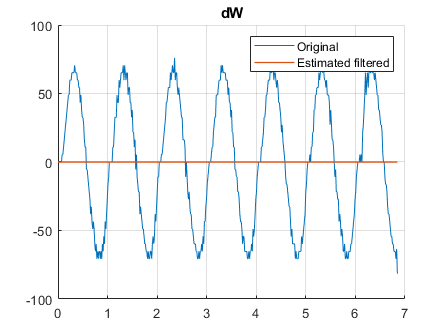


figure
hold on
plot(time(start:finish), dw_orig(start:finish))
plot(time(start:finish), x_arr(2, (start:finish)), "LineWidth", 1)
hold off
grid on
title("dW")
xlim("auto")
ylim("auto")
% ylim([-60 60])
legend("Original", "Estimated filtered")

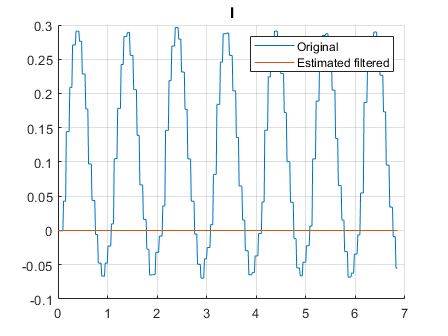


figure
hold on
plot(time(start:finish), current(start:finish))
plot(time(start:finish), x_arr(3, (start:finish)))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

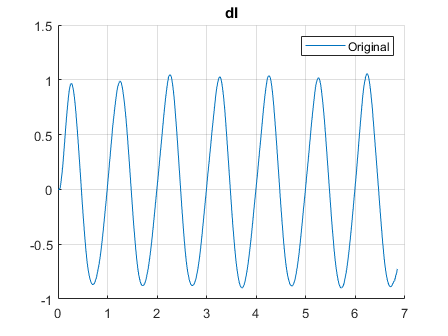


figure
hold on
plot(time(start:finish), dI_arr(start:finish))
hold off
grid on
title("dI")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

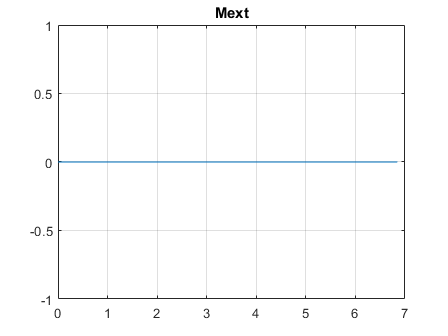


figure
plot(time, Mext_arr)
grid on
title("Mext")
xlim("auto")
ylim("auto")

Ah = [-eLam/eJ eKm/eJ; -eKw/eL -eR/eL];
Bh = [-1/eJ 0; 0 1/eL];
C = [1 0; 0 1];
D = [0 0; 0 0];

% A;
A = Ah;
% B;
B = Bh;

Amp = 5.7/2;
Bias = 5.7/2;
W = 1;
fi = 3.1415;
% Mext = 6e-3;
Mext = 0;
U_nominal = 5.9;

Const_input = [Amp Bias W fi Mext];

out1 = sim('motor_model_sim.slx', tf);
o = out1.simout;

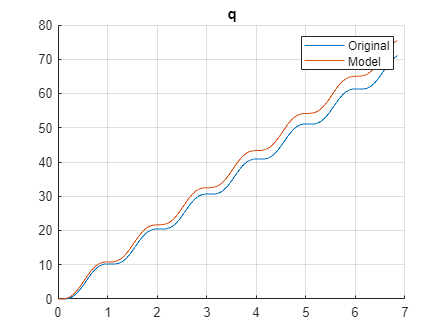

figure
hold on
plot(time, q_orig)
plot(o.q)
hold off
grid on
title("q")
legend("Original", "Model")

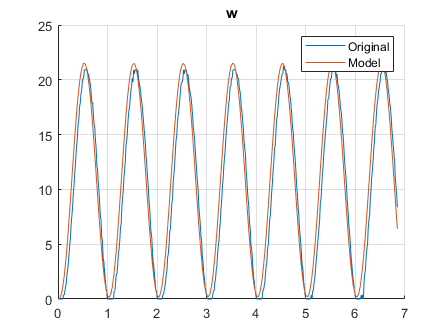


figure
hold on
plot(time, w_orig)
plot(o.w)
hold off
grid on
title("w")
legend("Original", "Model")

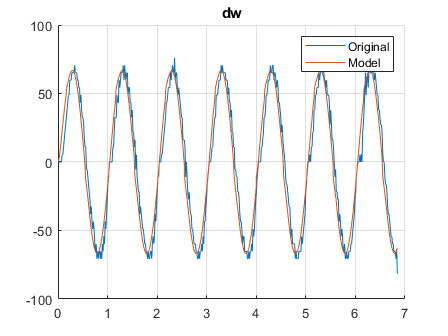


figure
hold on
plot(time, dw_orig)
plot(o.dw)
hold off
grid on
title("dw")
legend("Original", "Model")

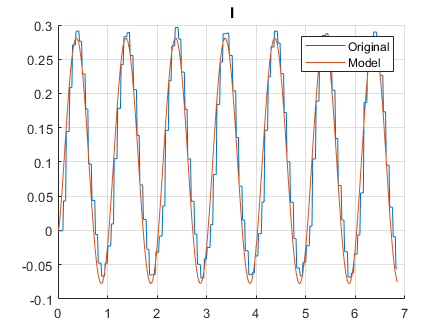


figure
hold on
plot(time, current)
plot(o.I)
hold off
grid on
title("I")
legend("Original", "Model")


% figure
% hold on
% plot(time, dI_arr)
% plot(o.dI)
% hold off
% grid on
% title("dI")
% legend("Original", "Model")